clear
newcolor = [228 26 28
            55 126 184
            77 175 74
            152 78 163
            255 127 0]/255

newcolor =     0.8941    0.1020    0.1098
    0.2157    0.4941    0.7216
    0.3020    0.6863    0.2902
    0.5961    0.3059    0.6392
    1.0000    0.4980         0


colororder(newcolor);
rng(1)
N = 10;
M = 5000;
m = 1;
c = 1;
theta = zeros(2,M);
theta(:,1) = [m;c];

theta_reg = zeros(2,M);
theta_reg(:,1) = [m;c];

for i = 2:M
    x = [-1;1;2*rand(N-2,1)-1];
    y = m*x + c + 1.5*randn(N,1);
    
    X = [x ones(N,1)];
    theta(:,i) = (X'*X)\(X'*y);
    theta_reg(:,i) = (X'*X + 3*eye(2))\(X'*y);

    MSE(i,1) = sum( (theta(:,i) - [m; c]).^2 );
    MSE_reg(i,1) = sum( (theta_reg(:,i) - [m; c]).^2 );
    

%     subplot(2,2,1)
%     p = plot(x, [x ones(N,1)]*theta(:,1:i), ...
%              x, [x ones(N,1)]*theta_reg(:,i),...
%              x, [x ones(N,1)]*theta(:,1), ...
%              x, y, 'k.','MarkerSize',10);
%     for j = 2:i-1
%         p(j).LineWidth = 0.5; p(j).Color = 0.7*[1 1 1];
%     end
%     p(i).LineWidth = 2; p(i).Color = newcolor(1,:);
%     p(i+1).LineWidth = 2; p(i+1).Color = newcolor(2,:);
%     p(i+2).LineWidth = 2; p(i+2).Color = 'k';
%     axis([-1 1 -1 3])
%     axis square
%     
%     subplot(2,2,3)
%     pt = plot(theta(1,1:i), theta(2,1:i), '.',...
%               theta_reg(1,1:i), theta_reg(2,1:i), '.', ...
%               theta(1,[1, i]), theta(2,[1, i]), '-o',...
%               theta_reg(1,[1, i]), theta_reg(2,[1, i]), '-o', ...
%               m, c, '.');
%     pt(1).MarkerSize = 5; 
%     pt(2).MarkerSize = 5; 
%     pt(3).MarkerSize = 5; pt(3).MarkerFaceColor = newcolor(1,:); pt(3).LineWidth = 2; pt(3).Color = newcolor(1,:);
%     pt(4).MarkerSize = 5; pt(4).MarkerFaceColor = newcolor(2,:); pt(4).LineWidth = 2; pt(4).Color = newcolor(2,:);
%     pt(5).MarkerSize = 20; pt(5).MarkerFaceColor = 'k'; pt(5).Color = 'k';
%     axis([-2 4 -2 4])
%     axis square
% 
%     subplot(2,2,2)
%     bh = barh((1:i)/i, sort(MSE));
%     bh.EdgeColor = 'none';
%     axis([0 2.4 0 1])
% 
%     subplot(2,2,4)
%     bh = barh((1:i)/i, sort(MSE_reg),'FaceColor',[55 126 184]/255);
%     bh.EdgeColor = 'none';
%     axis([0 2.4 0 1])
% 
%     drawnow
end

edges = linspace(0, 2.5, 100);
pMSE_emp = histcounts(MSE, edges,'Normalization','pdf');
pMSE_reg_emp = histcounts(MSE_reg, edges,'Normalization','pdf');

mu = mean(MSE)

mu = 0.7659

mu_reg = mean(MSE_reg)

mu_reg = 0.5271

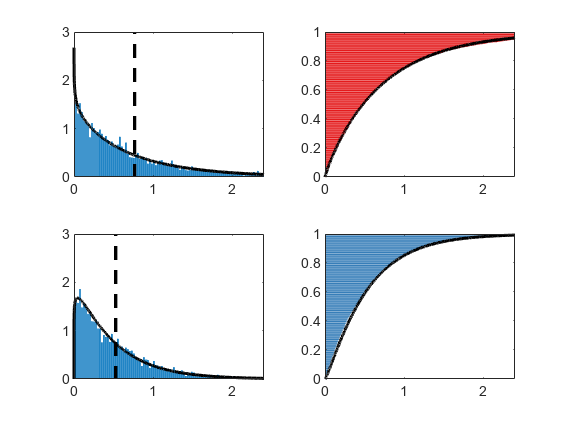


figure
subplot(2,2,2)
x = sort(MSE);
bh = barh((1:i)/i, x,'FaceColor',newcolor(1,:));
hold on
plot(x, gamcdf(x, 0.9, 0.8),'k','LineWidth',2)
hold off
bh.EdgeColor = 'none';
axis([0 2.4 0 1])

subplot(2,2,4)
bh = barh((1:i)/i, sort(MSE_reg),'FaceColor',newcolor(2,:));
hold on
plot(x, gamcdf(x, 1.2, 0.45),'k','LineWidth',2)
hold off
bh.EdgeColor = 'none';
axis([0 2.4 0 1])

subplot(2,2,1)
bh = bar(edges(2:end), pMSE_emp);
hold on
plot(x, gampdf(x, 0.9, 0.8),'k','LineWidth',2)
plot([mu mu], [0 3], 'k--','LineWidth',2)
hold off
bh.EdgeColor = 'none';
axis([0 2.4 0 3])

subplot(2,2,3)
bh = bar(edges(2:end), pMSE_reg_emp);
hold on
plot(x, gampdf(x, 1.1, 0.45),'k','LineWidth',2)
plot([mu_reg mu_reg], [0 3], 'k--','LineWidth',2)
hold off
bh.EdgeColor = 'none';
axis([0 2.4 0 3])